# 衰落信道

#### 重要物理量：

PDP(power delay profile)功率时延分布

平均过量时延：PDP对功率的平均

RMS(root mean square)均方根时延扩展

#### 频率色散引起的衰落：时间选择性衰落信道（多普勒）

#### 时间色散引起的衰落：频率选择性衰落信道（多径）

LOS环境接收信号PDF（probability density function,散射分量AoA概率密度函数）服从莱斯分布，NLOS环境接收信号PDF服从瑞利分布

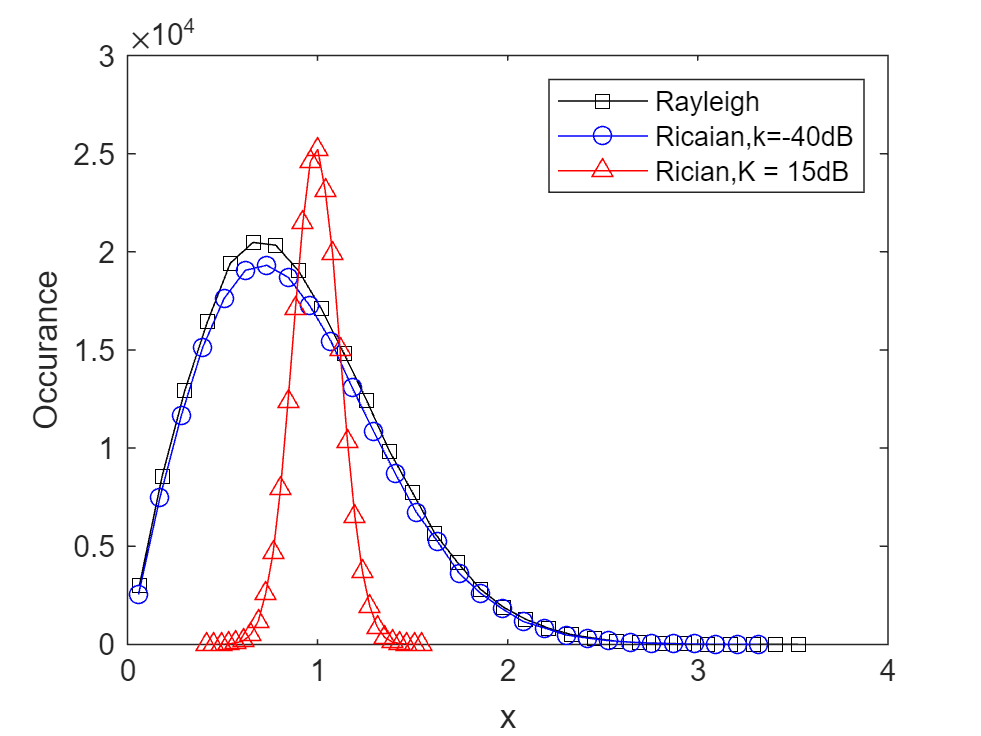

clear;
N = 200000;
level = 30;
K_dB = [-40 15];
Rayleigh_ch = zeros(1,N);
Rician_ch = zeros(2,N);
gss = ['k-s';'b-o';'r-^'];
% 瑞利模型
Rayleigh_ch = Ray_model(N);
[temp,x] = hist(abs(Rayleigh_ch(1,:)),level);
figure()
plot(x,temp,gss(1,:))
hold on;
% 莱斯模型
for i=1:length(K_dB)
    Rician_ch(i,:) = Ric_model(K_dB(i),N);
    [temp x] = hist(abs(Rician_ch(i,:)),level);
    plot(x,temp,gss(i+1,:));
end
xlabel('x')
ylabel('Occurance')
legend('Rayleigh','Ricaian,k=-40dB','Rician,K = 15dB')

function H=Ray_model(L)
    %输入：
    %       L:信道实现数
    % 输出：
    %         H：信道向量
    H = (randn(1,L)+1j*randn(1,L))/sqrt(2);
end

function H = Ric_model(K_dB,L)
    % 输入：
    %     K_dB: K因子
    %     L：信道实现数
    % 输出：
    %     H：信道向量
    K = 10^(K_dB/10);
    H = sqrt(K/(K+1))+sqrt(1/(K+1))*Ray_model(L);
end